### Load the data

Download the data from here.

Load the data into a table (you might need to change the folder location).

data = readtable('../Week 01/memorycandy.txt');

### Tidy up the data to make it easier to work with.

data= sortrows(data,'CodeName'); %Sort by names (now will be in alphabetical order)
data.CodeName = categorical(data.CodeName); % make categorical to make easier to choose subsets
data.Group = categorical(data.Group); % make categorical to make easier to choose subsets

### Determine how many correct answers each person gave

Make lists of the two answers. 

round1 = {'read','pages','letters','school','study','reading','stories','sheets','pencil','cover'};
round2 = {'house','apple','shoe','book','pencil','flag','rock','train','ocean','glass'};


Loop through all the data and count how many correct. The CorrectInOrder variable marks whether each word in the round1 or round2 list was included in a person's submission (in an order matching the order of round1 or round 2). This results are fairly strict. If someone wrote a singular form of a plural word, this is marked incorrect. You are welcome to update the results to be more lenient (but it's a little annoying to implement). 

The values in NumCorrect sum up how many of the words in round1 or round2 each person correctly recorded.

for i = 1:size(data,1) % loop through each answer
    listofwords = unique(data{i,2:11}); % pull the answers out for each person, and put them into cells to make matlab happy
    if data{i,'List'}== 1
        for w = 1:length(round1) %see if each word in the round1 list is included in the responses
            data.CorrectInOrder(i,w) = max(strcmp(round1(w),listofwords));
        end
        data.NumCorrect(i) = sum(data.CorrectInOrder(i,:));  %add up all that were correct     
        data.List1ContainsBook(i) = sum(contains(listofwords,'book','IgnoreCase',true)) > 0; %Did list 1 responses contain the critical false lure?
        data.List1ContainsPencil(i) = sum(contains(listofwords,'pencil','IgnoreCase',true)) > 0;
        data.List1ContainsHouse(i) = sum(contains(listofwords,'house','IgnoreCase',true)) > 0;
    elseif data{i,"List"} ==2
        for w = 1:length(round2) %see if each word in the round2 list is included in the responses
            data.CorrectInOrder(i,w) = max(strcmp(round2(w),listofwords));
        end
        data.NumCorrect(i) = sum(data.CorrectInOrder(i,:)); %add up all that were correct
    end
end

### Create plots to look primacy and recency.

These plots are just to explore the data and make sure things look reasonable and to see if our findings replicate the results of a famous paper. You won't need these plots for the rest of the analysis, but I wanted to shared with you whether our data showed the primacy (remember the early words) and recency (remember the last word) effects. These effects are shown clearly in Figure 1 of the Roediger and McDermott paper [https://pdfs.semanticscholar.org/9425/1836c4c160574b8887362847795da66c2c81.pdf).](https://pdfs.semanticscholar.org/9425/1836c4c160574b8887362847795da66c2c81.pdf).) Note, they used a moving average to smooth the data.

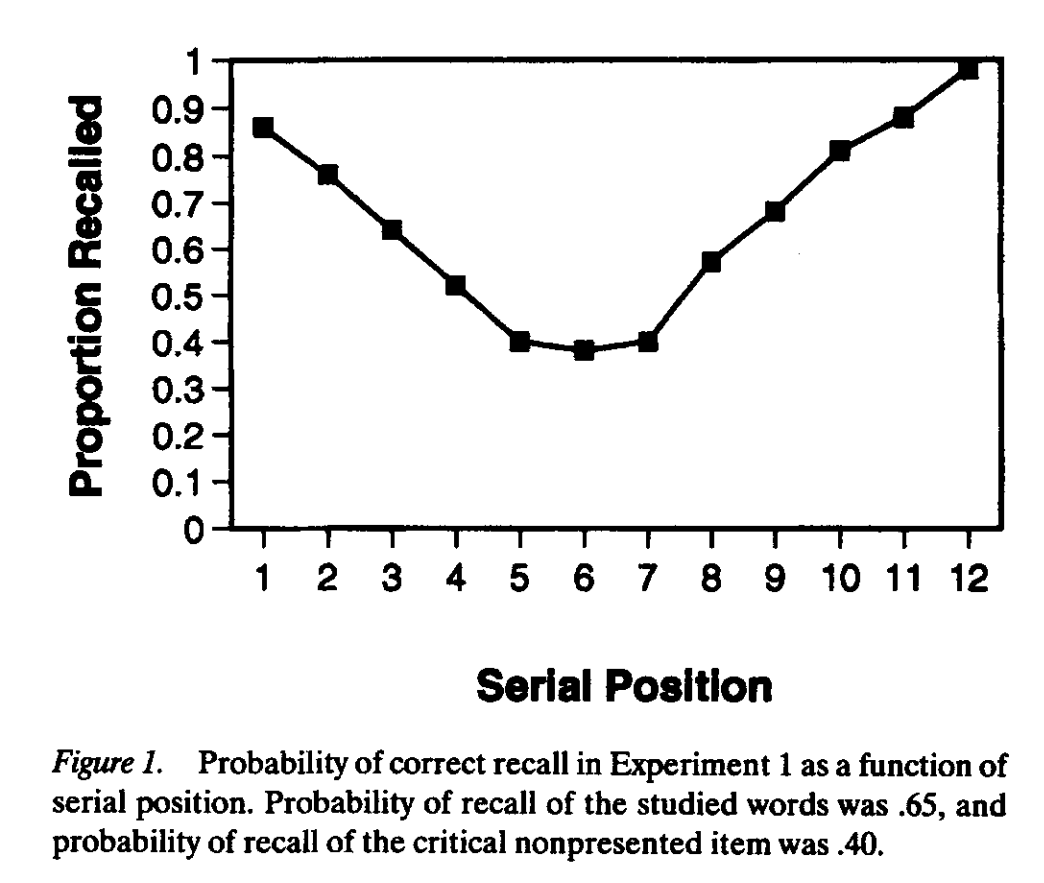

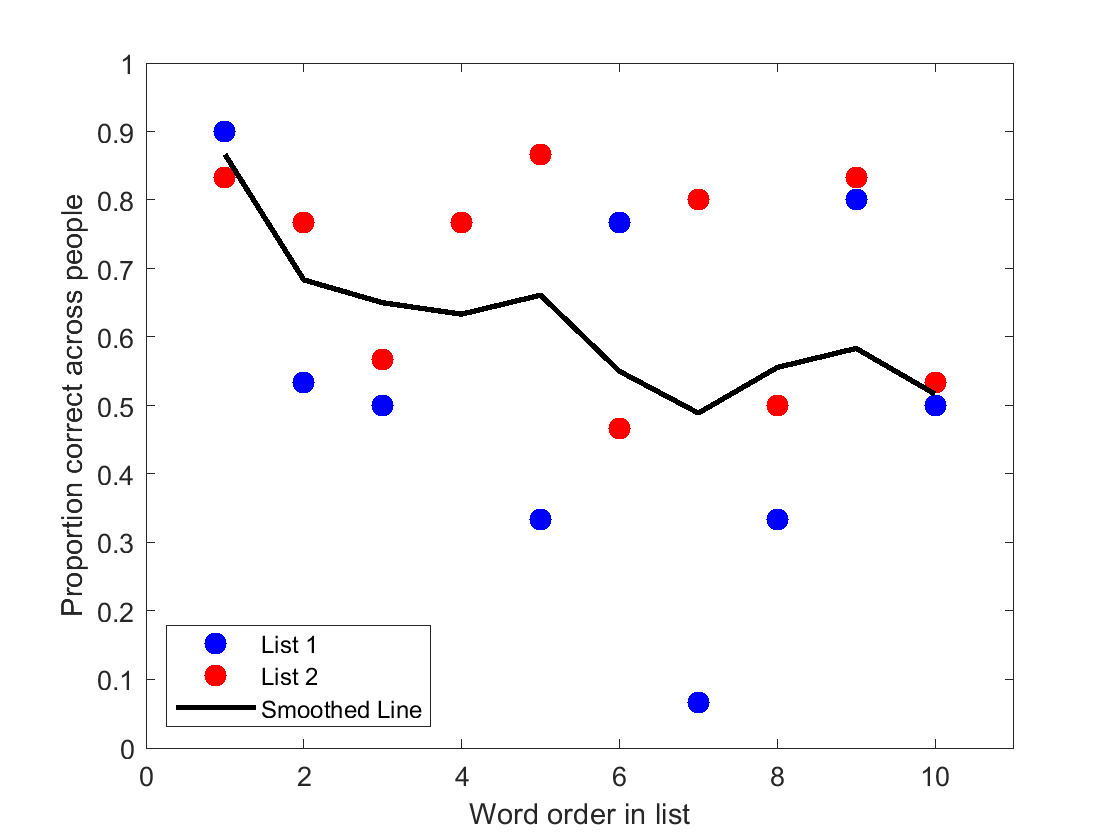

list1order = mean(data.CorrectInOrder(data.List==1,:));
list2order = mean(data.CorrectInOrder(data.List==2,:));

figure;
plot(1:10,list1order,'bo','MarkerSize',8,'MarkerFaceColor',"blue"); hold on;
%plot(1:10,smooth(list1order,3),'b','LineWidth',2); 
plot(1:10, list2order,'ro','MarkerSize',8,'MarkerFaceColor',"red");
plot(1:10, smooth(mean([list1order; list2order]),3),'k','LineWidth',2);
axis([0,11, 0, 1]); ylabel('Proportion correct across people'); xlabel('Word order in list'); legend({'List 1','List 2','Smoothed Line'},'Location',"southwest"); hold off;

The dots represent the data for our two lists. The black line represents a smoothed line to more closely represent the work shown in Figure 1 of the paper. We see the primacy effect, but not the recency effect. We may not expect to see the recency effect, since we waiting quite a while before recalling the lists.